In this document we will explore the concept of a "valid design" for a single variable-curvature segment. We will first implement the forward kinematics of a rod with linear curvature. Then, we will compute the externally induced forces and moments along it at each point, and plot these points in the reaction space. Finally, we will compute the internal reaction forces along an arm held at that shape, and also plot these points within the reaction space.

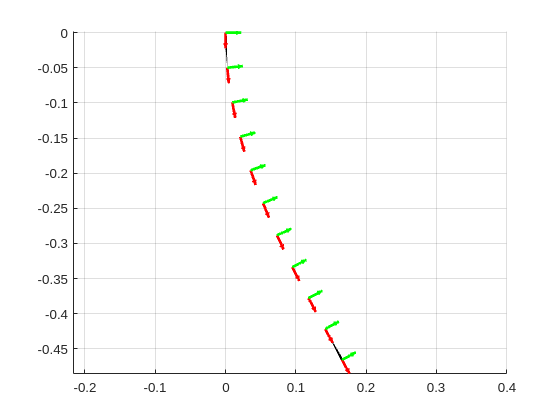

% Define arm base curve
a = -1;
b = 1;

l = 0.5;
f_affine_curvature = @(s) [
    l*ones(size(s));
    zeros(size(s));
    a*s + b
];

g_0 = Pose2.hat([0, 0, -pi/2]);
N_poses = 10;
s = linspace(0, 1, N_poses);
poses = f_calc_poses(g_0, f_affine_curvature, N_poses);
segment_twists = f_affine_curvature(s);

ax = axes(figure());
plot_poses(poses, ax);
grid on

Now let's apply a load to the tip of this rod and consider the reactions across it:

Q_tip = [0; -10; 0];
g_tip = poses(:, :, end);

% TODO: Replace this with a call to our function
q = zeros(3, N_poses);
for i = 1 : N_poses
    g_i = poses(:, :, i);
    g_i_tip = inv(g_i) * g_tip;
    g_ucirc_right_tip = Pose2.left_lifted_action(g_tip)' * Q_tip;
    g_ucirc_right_s = inv(Pose2.adjoint(g_i_tip))' * g_ucirc_right_tip;

    q(:, i) = g_ucirc_right_s;
end

Now given the pressures of each muscle in the arm, compute the internal reaction force supplied along the length of the arm

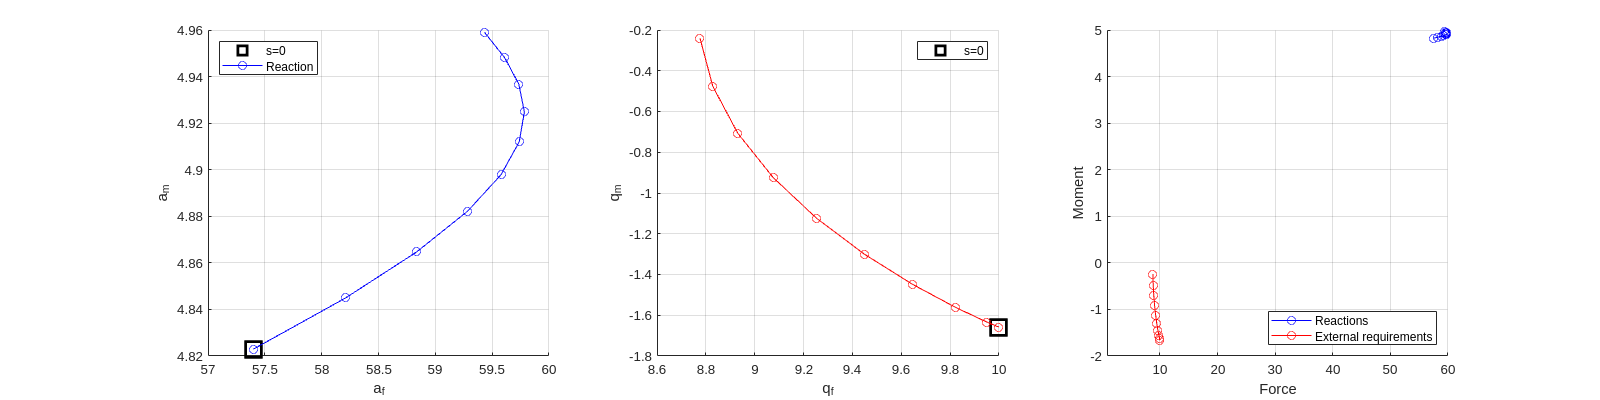

p = [15; 0; 15; 0]; %kPa

% Define actuator forces
f_bellow = @JacobBellowMechanics.actuator_force;
f_muscle = @GinaMuscleMechanics.actuatorForce_key;
fs = {f_bellow, f_muscle, f_muscle, f_bellow};

rho_outer = 0.08;
rho_inner = 0.015;

rhos = [-rho_outer, -rho_inner, rho_inner, rho_outer];

% TODO: Replace this with a call to our function
% Compute the strains of each rods
l_0 = 0.5;
strain_o = (l - l_0) / l_0;

mat_A = [
1, 1, 1, 1;
0, 0, 0, 0;
-rhos;
];

lengths = zeros(4, N_poses);
strains = zeros(4, N_poses);
forces = zeros(4, N_poses);
for i = 1 : length(rhos)
    lengths(i, :) = segment_twists(1, :) - rhos(i) * segment_twists(3, :);
    strains(i, :) = (lengths(i, :) - l_0) / l_0;
    for j = 1 : length(forces)
        forces(i, j) = fs{i}(strains(i, j), p(i));
    end
end

reaction_forces = mat_A * forces;

% Now we plot the two against each other
figure("position", [0, 0, 1600, 400])
subplot(1, 3, 1)
hold on
plot(reaction_forces(1, 1), reaction_forces(3, 1), "ksquare", "markersize", 15, "linewidth", 3)
plot(reaction_forces(1, :), reaction_forces(3, :), "b-o")
legend("s=0", "Reaction", location="Northwest")
xlabel("a_f")
ylabel("a_m")
grid on

subplot(1, 3, 2)
hold on
plot(q(1, 1), q(3, 1), "ksquare", "markersize", 15, "linewidth", 3);
plot(q(1, :), q(3, :), 'r-o');
xlabel("q_f")
ylabel("q_m")
legend("s=0")
grid on

subplot(1, 3, 3)
hold on
plot(reaction_forces(1, :), reaction_forces(3, :), "b-o");
plot(q(1, :), q(3, :), "r-o");
xlabel("Force")
ylabel("Moment")
legend("Reactions", "External requirements", location="southeast")
grid on

The crucial questions for extending our previous work to the variable curvature arm are:

- What will happen to this plot when we traverse the pressure contour? 

- How can we read "designability" from the variable curvature arm's pressure contour?

struct_design = struct();
struct_design.mat_A = mat_A;
struct_design.l_0 = l_0;
struct_design.fs = fs;
struct_design.g_0 = g_0;
struct_design.rhos = rhos;

tic
default_segment_twists = zeros(size(segment_twists));
default_segment_twists(1, :) = l_0;
default_segment_twists(3, :) = 1e-5;

Q_tip = [0; 0; 0];
opts = optimoptions("fsolve", MaxFunctionEvaluations=4e5, MaxIterations=5e3, StepTolerance=1e-8, FunctionTolerance=1e-8, Algorithm="levenberg-marquardt");
f = @(mat_in) check_equilibrium(mat_in, Q_tip, p, struct_design);
[soln_fsolve, res, ~, output, J_end] = fsolve(f, default_segment_twists, opts);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


disp(res)

   1.0e-12 *

   -0.3197   -0.3197    0.1350   -0.3197   -0.3197    0.1350   -0.3197   -0.3197   -0.3197   -0.3197
   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
   -0.0044   -0.0044    0.0027   -0.0044   -0.0044    0.0022   -0.0044   -0.0044   -0.0049   -0.0044



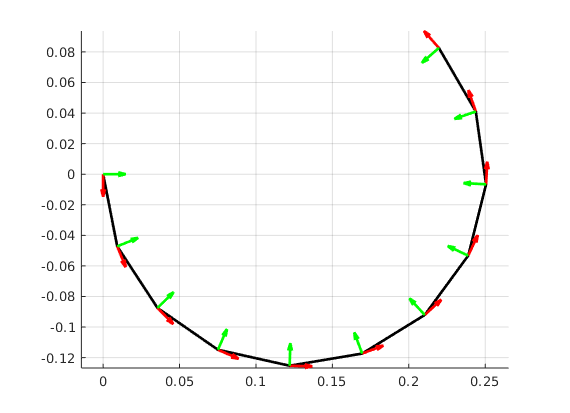

poses = calc_poses(g_0, soln_fsolve);
ax = axes(figure());
plot_poses(poses, ax);
grid on
set(gcf, "Visible", true)

toc

Elapsed time is 1.625463 seconds.


function poses = f_calc_poses(g_0, f_segment_twists, N_poses)
    s = linspace(0, 1, N_poses);
    mat_segment_twists = f_segment_twists(s);
    poses = calc_poses(g_0, mat_segment_twists);
end

function plot_poses(poses, ax, linestyle)

    arguments
        poses
        ax
        linestyle="k-";
    end

    axis_length = 0.15;

    % Extract position components
    p_x = squeeze(poses(1, 3, :));
    p_y = squeeze(poses(2, 3, :));

    % Extract x unit vector components
    x_u = squeeze(poses(1, 1, :));
    x_v = squeeze(poses(2, 1, :));

    y_u = squeeze(poses(1, 2, :));
    y_v = squeeze(poses(2, 2, :));

    % Plot
    hold(ax, "on")
    plot(ax, p_x, p_y, linestyle, "linewidth", 2);
    quiver(ax, p_x, p_y, x_u, x_v, axis_length, "red", "linewidth", 2);
    quiver(ax, p_x, p_y, y_u, y_v, axis_length, "green", "linewidth", 2);
    axis(ax, "equal")
end